
clc
clear
close all

data = readmatrix("data_vysledek.xlsx");

f = data(:, 2);
adxl_x = data(:, 4:6);
adxl_y = data(:, 7:9);
bno_x = data(1:13, 11:13);
bno_y = data(1:13, 14:16);

## BNO PLOT


f_meas = f(1:13);
K_meas = mean(bno_x(:,1:3), 2) / 0.981;

model = @(p,f) p(1) ./ sqrt(1 + (f./p(2)).^2) ./ sqrt(1 + (f./p(3)).^2);
% p = [K0, f1, f2]

p0 = [1, 10, 30];   % dobrý start

p = lsqcurvefit(model, p0, f_meas, K_meas);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


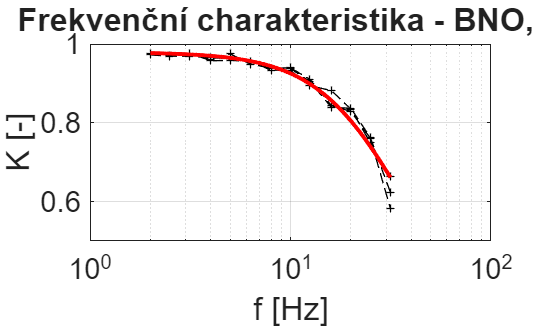


K0 = p(1);
f1 = p(2);
f2 = p(3);

f_fit = logspace(log10(min(f_meas)), log10(max(f_meas)), 300);
K_fit = model(p, f_fit);

figure;
plot(f(1:13), bno_x(:, 1)/0.981, "k+--", "LineWidth", 1);
hold on
plot(f(1:13), bno_x(:, 2)/0.981, "k+--", "LineWidth", 1);
hold on
plot(f(1:13), bno_x(:, 3)/0.981, "k+--", "LineWidth", 1);
hold on
plot(f_fit, K_fit, "r-", "LineWidth", 3);
title("Frekvenční charakteristika - BNO, Y", "FontSize",24);
xlabel("f [Hz]", "FontSize",22);
ylabel("K [-]", "FontSize",22);
xscale("log");
ylim([0.5 1])
xlim([1 100]);
ax = gca;
ax.FontSize = 22; % sets tick label font size
%legend(["měření 1", "měření 2", "měření 3"])
grid on

## ADXL PLOT

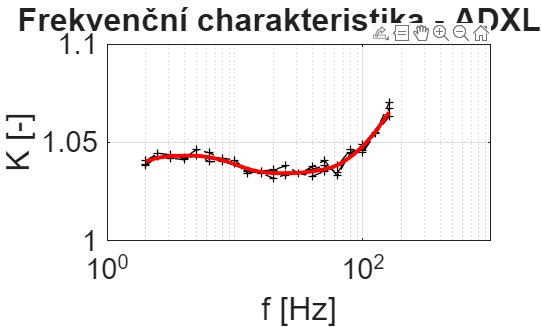

f_meas = f;
K_meas = mean(adxl_y(:,1:3), 2) / 0.1;

% fit
fitresult = fit(log10(f_meas), K_meas, 'smoothingspline', SmoothingParam=0.999);

% jemná osa
f_fit = logspace(log10(min(f_meas)), log10(max(f_meas)), 400);
K_fit = feval(fitresult, log10(f_fit));

figure;
plot(f, adxl_y(:, 1)/0.1, "k+--", "LineWidth", 1);
hold on
plot(f, adxl_y(:, 2)/0.1, "k+--", "LineWidth", 1);
hold on
plot(f, adxl_y(:, 3)/0.1, "k+--", "LineWidth", 1);
hold on
plot(f_fit, K_fit, "r-", "LineWidth", 3);
title("Frekvenční charakteristika - ADXL, Y", "FontSize",24);
xlabel("f [Hz]", "FontSize",22);
ylabel("K [-]", "FontSize",22);
xscale("log");
ylim([1 1.1])
xlim([1 1000]);
ax = gca;
ax.FontSize = 22; % sets tick label font size
%legend(["měření 1", "měření 2", "měření 3"])
grid on

## ADXL X plot

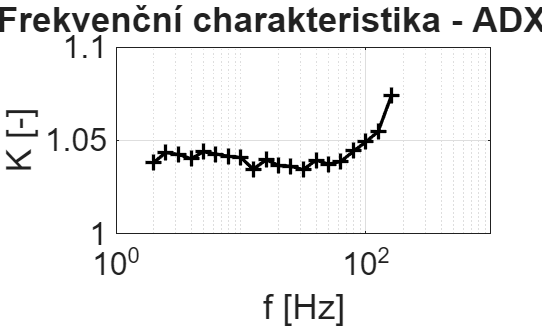

adxl_x_mean = mean(adxl_x/0.1, 2);

figure;
plot(f, adxl_x_mean, "k+-", "LineWidth", 2.5, "MarkerSize", 12);

title("Frekvenční charakteristika - ADXL, X", "FontSize",28);
xlabel("f [Hz]", "FontSize",24);
ylabel("K [-]", "FontSize",24);
xscale("log");
ylim([1 1.1]);
xlim([1 1000]);
ax = gca;
ax.FontSize = 24; % sets tick label font size
grid on

## ADXL Y plot

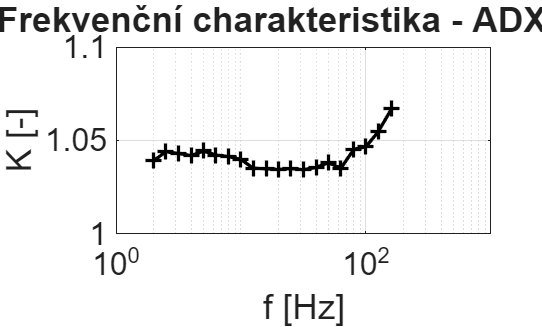

adxl_y_mean = mean(adxl_y/0.1, 2);

figure;
plot(f, adxl_y_mean, "k+-", "LineWidth", 2.5, "MarkerSize", 12);

title("Frekvenční charakteristika - ADXL, Y", "FontSize",28);
xlabel("f [Hz]", "FontSize",24);
ylabel("K [-]", "FontSize",24);
xscale("log");
ylim([1 1.1]);
xlim([1 1000]);
ax = gca;
ax.FontSize = 24; % sets tick label font size
grid on

## BNO X plot

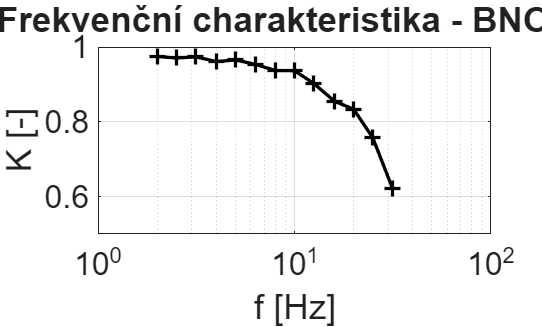

bno_x_mean = mean(bno_x/0.981, 2);

figure;
plot(f(1:13), bno_x_mean, "k+-", "LineWidth", 2.5, "MarkerSize", 12);

title("Frekvenční charakteristika - BNO, X", "FontSize",28);
xlabel("f [Hz]", "FontSize",24);
ylabel("K [-]", "FontSize",24);
xscale("log");
ylim([0.5 1]);
xlim([1 100]);
ax = gca;
ax.FontSize = 24; % sets tick label font size
grid on

## BNO Y plot

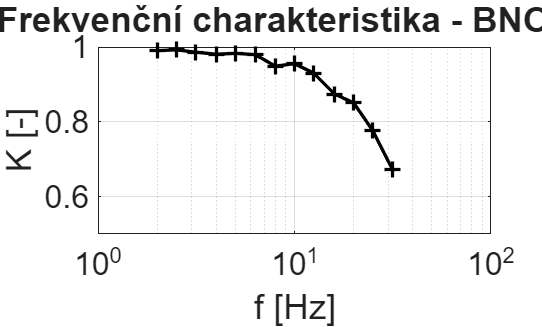

bno_y_mean = mean(bno_y/0.981, 2);

figure;
plot(f(1:13), bno_y_mean, "k+-", "LineWidth", 2.5, "MarkerSize", 12);

title("Frekvenční charakteristika - BNO, Y", "FontSize",28);
xlabel("f [Hz]", "FontSize",24);
ylabel("K [-]", "FontSize",24);
xscale("log");
ylim([0.5 1]);
xlim([1 100]);
ax = gca;
ax.FontSize = 24; % sets tick label font size
grid on